clc;
close all;
clear;

## Task 1: Setup Robot

add a forth row to the DH table to calculate the end-effector position add a forth frame for setup robot

% robot = rigidBodyJoint();

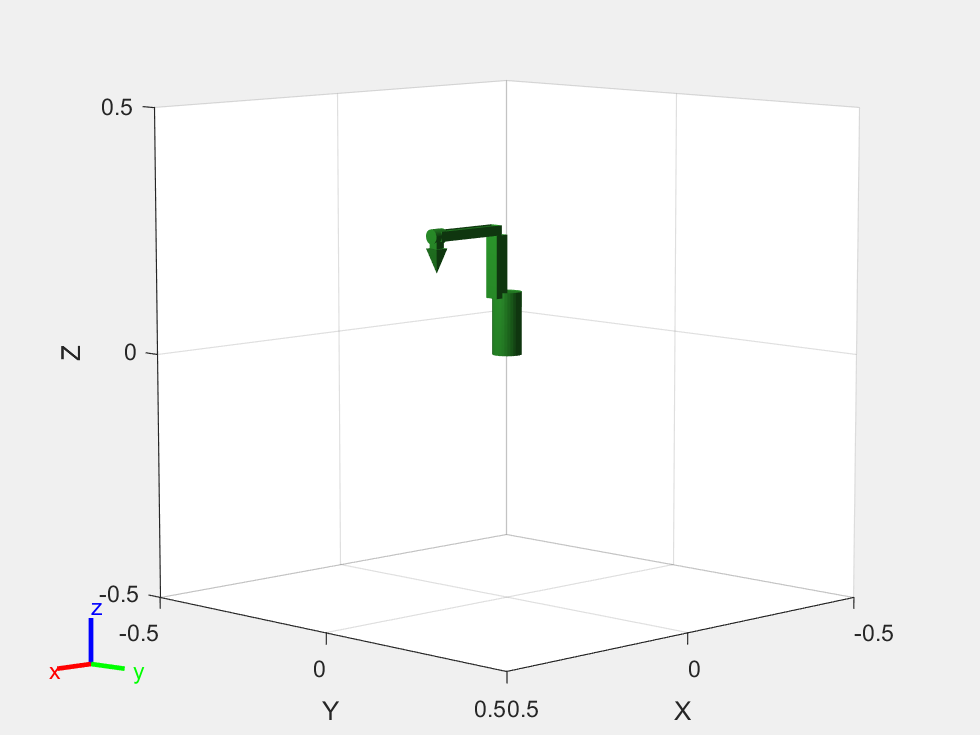

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
arm4 = rigidBody("arm4");
arm5 = rigidBody("arm5");
arm6 = rigidBody("arm6");

coll1 = collisionCylinder(0.03,0.127);    % cylinder: radius,length
coll1.Pose = trvec2tform([0 0 -0.127/2]); % centre

coll2 = collisionBox(0.127,0.03,0.03);  % box:length,width,height (x,y,z)
coll2.Pose = trvec2tform([0.108/2 0 0]);  % centre

coll3 = collisionBox(0.02,0.168, 0.03); % box:length,width,height (x,y,z)
coll3.Pose = trvec2tform([0.02 0.16898/2 0]); % centre

coll4 = collisionCylinder(0.015,0.03); % cylinder: radius,length
coll4.Pose = trvec2tform([0 0 0]); % centre

coll5 = collisionBox(0.02,0.02429,0.02); % box:length,width,height (x,y,z)
coll5.Pose = trvec2tform([0 0.02429/2 0]); % centre


tribox = zeros(6,3); %6 by 3 mesh
tribox(1,:) = [0.015, 0.015,   0];
tribox(2,:) = [0.015, -0.015,  0];
tribox(3,:) = [-0.015,  -0.01, 0];
tribox(4,:) = [-0.015, 0.015, 0];
tribox(5,:) = [0, 0, -0.05];
tribox(6,:) = [0, 0, -0.05];
coll6 = collisionMesh(tribox); % cylinder: radius,length
coll6.Pose = trvec2tform([0 0 0]); % centre


addCollision(arm1,coll1)           % add Collision to the links
addCollision(arm2,coll2)
addCollision(arm3,coll3)
addCollision(arm4,coll4)
addCollision(arm5,coll5)
addCollision(arm6,coll6)


% set joints as revolute joints  
jnt1 = rigidBodyJoint("jnt0","revolute");
jnt2 = rigidBodyJoint("jnt1","revolute");
jnt3 = rigidBodyJoint("jnt2","revolute");
jnt4 = rigidBodyJoint("jnt3","revolute");
jnt5 = rigidBodyJoint("jnt4","revolute");
jntend = rigidBodyJoint("endeffector_joint","revolute");


%           a        alpha      d       theta      modified DH table 
dhparams = [0,   	   0,    	0.127,      0;
            0.029,    -pi/2,    0,        0;
            0.108,    0,    	0,        0;
            0.02,     -pi/2,    0.168,    0;
            0,        pi/2,     0,        0;
            0,        pi/2,    -0.02429,    0];
       
bodies = {base,arm1,arm2,arm3,arm4,arm5,arm6};  
joints = {[],jnt1,jnt2,jnt3,jnt4,jnt5,jntend};

jnt1.HomePosition = 0;
jnt2.HomePosition=-pi/2;
jnt3.HomePosition  = 0;
jnt4.HomePosition = 0;
% Coppelia pi/2
jnt5.HomePosition = pi/2;
jntend.HomePosition = 0;


figure("Name","Robot","Visible","on")               % Visualise the robot
for i = 2:length(bodies)
    setFixedTransform(joints{i},dhparams(i-1,:),"mdh");
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
    show(robot,"Collisions","on","Frames","off");
    drawnow;     
end

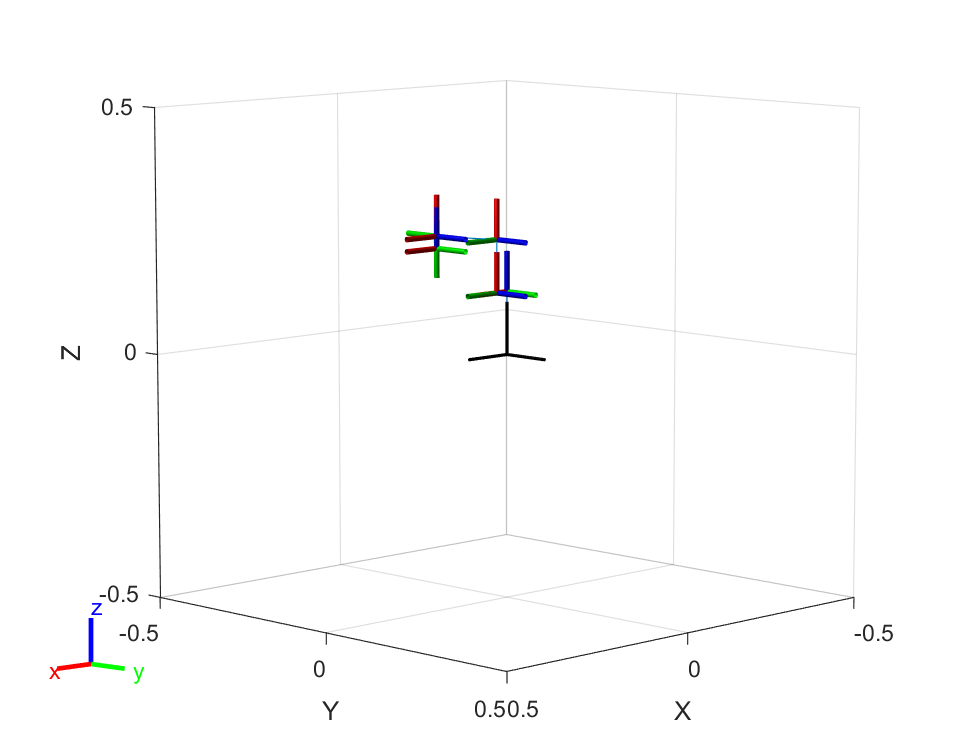

figure;
show(robot);

save('robot.mat','robot');

**Simulate rotating**

homeconfig = homeConfiguration(robot);    % Setting initial angle

test_angle = [-pi/4, 0, 0, 0, 0, 0];
%joint_pos_init = transform_angle(joint_pos_init);;
%deltaconfig = (transform_angle(test_angle))';     % Setting final angle
deltaconfig = test_angle';
d1 = 0.128;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;

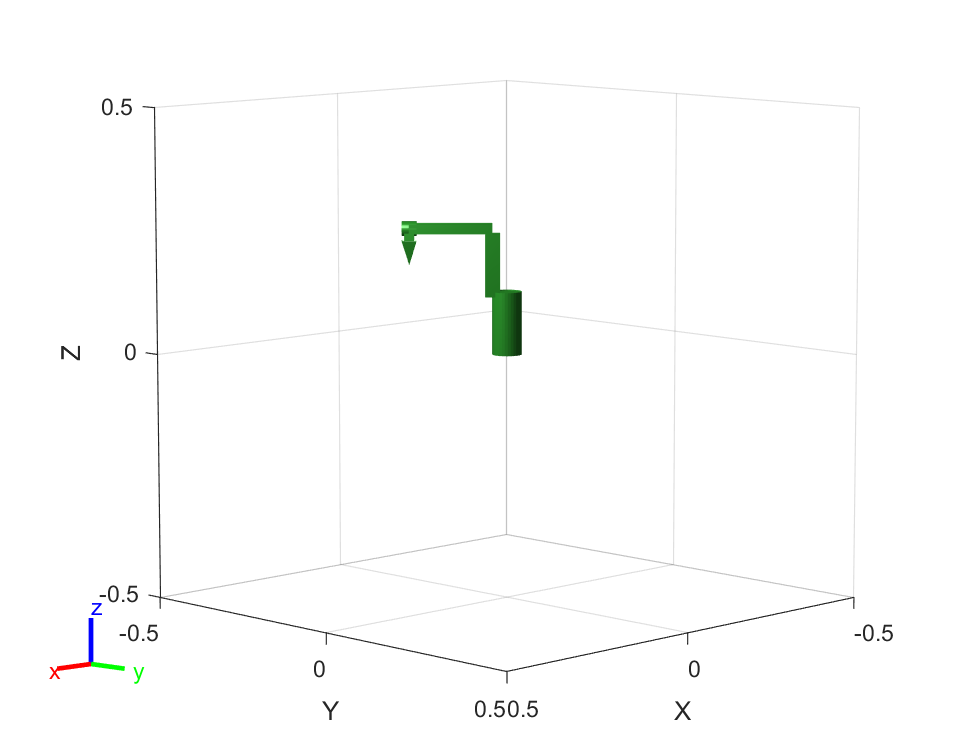

Initial = homeconfig;
Qd = deltaconfig;
Step = 20;
framesPerSecond = 15;
tip_positions = zeros([Step,3]);
for i = 1:Step
    q = Initial + Qd / Step * i;
    show(robot,q,"Collisions","on","Frames","off");
    F(i) = getframe(gcf) ;
    drawnow
end


% plot3(X, Y, Z, 'b', 'LineWidth', 2);
% hold on;
% plot3(tip_positions(:, 1),tip_positions(:, 2),tip_positions(:, 3),'r', 'LineWidth', 2);
% hold off;
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('Trajectory Plot');
% grid on;